% FINALPROJECT MATLAB SOURCE CODE
%
% TEAM 1 | ECE 550 | OSU WINTER 2023 TERM.
%
% NAME: OLUWASEGUN SOMEFUN and NAM NGUYEN.
% somefuno@oregonstate.edu
% nguynam4@oregonstate.ed


% Q1. 
% RC Time-constant
Tc = 1e-3 % 1 [ms]

Tc = 1.0000e-03

Tcinv = (1/Tc)

Tcinv = 1000

% state-state mat.
Ao = [1 1;
    0.25 1];
A = -Tcinv.*Ao;
% input-state mat.
Bo = [1 0;
    0.25 0.75];
B = Tcinv.*Bo;
% state-output mat.
C = [1 1;
    0 1];
% input-output (feed-through)
D = [0 0; 0 0];

states = ["${vc_{1}}{\bigl(t\bigr)}$", "${vc_{2}}{\bigl(t\bigr)}$"]

states = 1×2 string array
    "${vc_{1}}{\bigl(t\bigr)}$"    "${vc_{2}}{\bigl(t\bigr)}$"


inputs = ["${v_{1}}{\bigl(t\bigr)}$", "${v_{2}}{\bigl(t\bigr)}$"]

inputs = 1×2 string array
    "${v_{1}}{\bigl(t\bigr)}$"    "${v_{2}}{\bigl(t\bigr)}$"


outputs = ["${vo_{1}}{\bigl(t\bigr)}$", "${vo_{2}}{\bigl(t\bigr)}$"]

outputs = 1×2 string array
    "${vo_{1}}{\bigl(t\bigr)}$"    "${vo_{2}}{\bigl(t\bigr)}$"


% sampling time
dt = 0.01 * 1e-3 % 0.01 [ms]

dt = 1.0000e-05

% continuous-time state-space
sys = ss(A,B,C,D, ...
    'statename',states, ...
    'inputname', inputs, ...
    'outputname', outputs)


sys =
 
  A = 
                 ${vc_{1}}{\b  ${vc_{2}}{\b
   ${vc_{1}}{\b         -1000         -1000
   ${vc_{2}}{\b          -250         -1000
 
  B = 
                 ${v_{1}}{\bi  ${v_{2}}{\bi
   ${vc_{1}}{\b          1000             0
   ${vc_{2}}{\b           250           750
 
  C = 
                 ${vc_{1}}{\b  ${vc_{2}}{\b
   ${vo_{1}}{\b             1             1
   ${vo_{2}}{\b             0             1
 
  D = 
                 ${v_{1}}{\bi  ${v_{2}}{\bi
   ${vo_{1}}{\b             0             0
   ${vo_{2}}{\b             0             0
 
Continuous-time state-space model.



% CHECK: continuous-time poles, pole_i < 10
pole_c = pole(sys)

pole_c =         -500
       -1500


% CHECK: eigen-info
[Q,E,Qinv] = eig(sys.A)

Q =     0.8944    0.8944
   -0.4472    0.4472


E =         -500           0
           0       -1500


Qinv =     0.4472    0.4472
   -0.8944    0.8944



% Q5a. CHECK: controllability
cntrlmat = [B A*B];
rank_cntrlmat = rank(cntrlmat)

rank_cntrlmat = 2

cond = (rank_cntrlmat==2)

cond = logical
   1


if (cond)
    fprintf('[TRUE] sys is CONTROLLABLE')
else
    fprintf('sys NOT controllable')
end

[TRUE] sys is CONTROLLABLE


% Q6. CHECK: observability
obsvmat = [C; C*A];
rank_obsvmat = rank(obsvmat)

rank_obsvmat = 2

cond = (rank_obsvmat==2)

cond = logical
   1


if (cond)
    fprintf('[TRUE] sys is OBSERVABLE')
else
    fprintf('sys NOT observable')
end

[TRUE] sys is OBSERVABLE


% QUICK-CHECK: discretized sys. (built-in c2d)
sys = c2d(sys,dt,'zoh')


sys =
 
  A = 
                 ${vc_{1}}{\b  ${vc_{2}}{\b
   ${vc_{1}}{\b        0.9901     -0.009901
   ${vc_{2}}{\b     -0.002475        0.9901
 
  B = 
                 ${v_{1}}{\bi  ${v_{2}}{\bi
   ${vc_{1}}{\b      0.009938    -3.725e-05
   ${vc_{2}}{\b      0.002475      0.007463
 
  C = 
                 ${vc_{1}}{\b  ${vc_{2}}{\b
   ${vo_{1}}{\b             1             1
   ${vo_{2}}{\b             0             1
 
  D = 
                 ${v_{1}}{\bi  ${v_{2}}{\bi
   ${vo_{1}}{\b             0             0
   ${vo_{2}}{\b             0             0
 
Sample time: 1e-05 seconds
Discrete-time state-space model.



% QUICK-CHECK: discrete-time poles, |pole_i| < 1 
pole_d = pole(sys) 

pole_d =     0.9950
    0.9851


% Q2.
% Sampled-data approximation (c2d custom) 
Ad = expm(A.*dt);
Bd = ((A)\(Ad-eye(2,2)))*B;
Cd = C;
Dd = D;
sys = ss(Ad,Bd,Cd,Dd,dt, ...
    'statename',states, ...
    'inputname', inputs, ...
    'outputname', outputs)


sys =
 
  A = 
                 ${vc_{1}}{\b  ${vc_{2}}{\b
   ${vc_{1}}{\b        0.9901     -0.009901
   ${vc_{2}}{\b     -0.002475        0.9901
 
  B = 
                 ${v_{1}}{\bi  ${v_{2}}{\bi
   ${vc_{1}}{\b      0.009938    -3.725e-05
   ${vc_{2}}{\b      0.002475      0.007463
 
  C = 
                 ${vc_{1}}{\b  ${vc_{2}}{\b
   ${vo_{1}}{\b             1             1
   ${vo_{2}}{\b             0             1
 
  D = 
                 ${v_{1}}{\bi  ${v_{2}}{\bi
   ${vo_{1}}{\b             0             0
   ${vo_{2}}{\b             0             0
 
Sample time: 1e-05 seconds
Discrete-time state-space model.



% CHECK: discrete-time poles, |pole_i| < 1 
pole_cd = pole(sys)

pole_cd =     0.9950
    0.9851


% SIM. inits.
x0 = [0;0]; % initial state
tFinal = 10 * 1e-3; % 10 [ms] = 0.01 secs
t = 0:dt:tFinal;

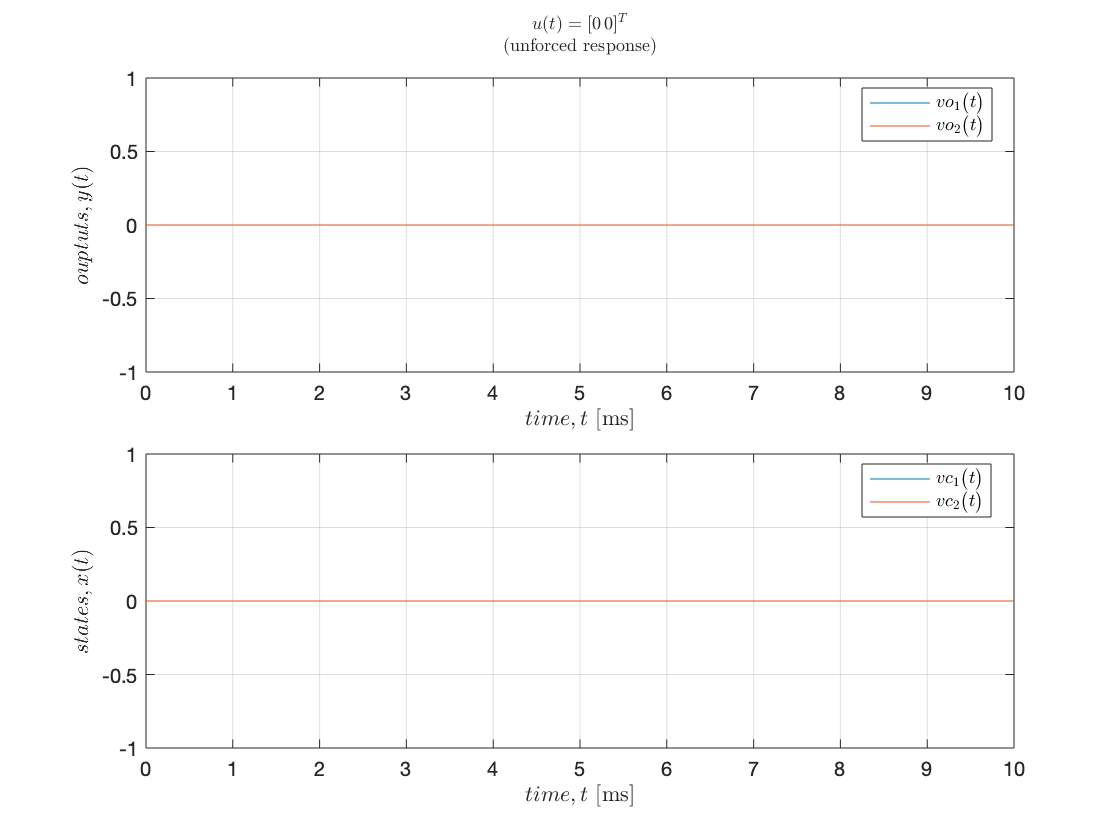

Unrecognized function or variable 'exportgraphics'.

Error in plotter (line 24)
exportgraphics(tlay,'savedplts/'+figsavename+'.png','Resolution',600)

% unforced response
% [y,tout,x] = initial(sys,x0, tFinal);
u = [0; 0].*t;
[y,x,tout] = c2dsim(sys,u,x0,t);
tms = tout*1e3;
f0 = {'$u{(t)} = [0\,0]^{T}$', '(unforced response)'};
plotter(tms,x,y,f0,states,outputs,"Q0");

%Q2a,b. constant input
u = [4; 1].*(t.^(0));
% [y,tout,x] = lsim(sys,u,t,x0,'zoh'); 
[y,x,tout] = c2dsim(sys,u,x0,t);
tms = tout*1e3;
f2aa = {'Q2a. $u{(t)} = [4\,1]^{T}$', '(simulated)'};
plotter(tms,x,y,f2aa,states,outputs,"Q2a");


% Q3. Analytical
% constant
xa = [
    3 - 0.5.*exp(-0.5.*t.*Tcinv) - 2.5.*exp(-1.5.*t.*Tcinv);
    1 + 0.25.*exp(-0.5.*t.*Tcinv) - 1.25.*exp(-0.5.*t.*Tcinv) 
    ];
ya = sys.C*xa;
xa = xa';
ya = ya';
f2aana = {'Q3a. $u{(t)} = [4\,1]^{T}$', '(analytical)'};
plotter(tms,xa,ya,f2aana,states,outputs,"Q3a");

%Q5b. designed input
u = [2; 1].*(t.^(0));
% [y,tout,x] = lsim(sys,u,t,x0,'zoh'); 
[y,x,tout] = c2dsim(sys,u,x0,t);
tms = tout*1e3;
f5b = {'Q5b. $u{(t)} = [2\,1]^{T}$', '(designed (constant) control input)'}; 
plotter(tms,x,y,f5b,states,outputs,"Q5b_0");

%Q5b2. designed input
% tt = (t).*Tcinv;
% at = exp(0.5.*tt);
% bt = exp(1.5.*tt);
% uc11 = zeros(2,numel(t));
% 
% af = exp(5);
% bf = exp(15); bf3 = 3*bf;
% uaa = -[(-af + bf3)/2;
%     (af + bf3)/4];
% 
% ub1 = ((10*(exp(10))) - (6*(exp(20))) + (6*(exp(30))) + 10);
% ub2 = ((-10*exp(10)) + (6*(exp(30))) + 4)/32;
% ubb = Tcinv*[ ub1/16 ub2;
%             ub2 ub1/64];
% 
% for i = 1:numel(tms)
% uc_i = -Tcinv*[ ...
%     0.25*((3*bt(i)) + at(i))  0.125*((3*bt(i)) - at(i));
%      -3*0.25*(at(i) - bt(i))  3*0.125*(at(i) + bt(i))
%     ];
% uc11(:,i) = (uc_i)*(ubb\uaa);
% end
% comment: floating-point errors issue in manual computation
tfms = 10e-3; % 10 [ms]
t0 = 0;
xt0 = [0; 0];
xtf = [1; 1];

a = @(th,tl) exp(-0.5.*Tcinv.*(th-tl));
b = @(th,tl) exp(-1.5.*Tcinv.*(th-tl));
tranmat = @(th,tl) [0.5.*(a(th,tl)+b(th,tl)) -(a(th,tl)-b(th,tl)); 
    -0.25.*(a(th,tl)-b(th,tl)) 0.5.*(a(th,tl)+b(th,tl)) ];
ua = xt0 - (tranmat(t0,tfms)*xtf);

ubfn = @(rho) (tranmat(0,rho)*B)*(tranmat(0,rho)*B)';
wgram = @(tzero,tf) integral(ubfn, tzero, tf, "ArrayValued",true);
ub = wgram(t0,tfms);

uc1 = zeros(2,numel(t));
for tk = 1:numel(tms)
uc = -(tranmat(t0,t(tk))*B)';
uc1(:,tk) = uc*(ub\ua);
end
[y,x,tout] = c2dsim(sys,uc1,x0,t);
tms = tout*1e3;
f5b = {'Q5b. $u{(t)} = \bigl(\Phi\bigl(0,t\bigr)B\bigr)^{T}\,W^{-1}(0,t_{f})\,\bigl[x\bigl(0\bigr)-\Phi\bigl(0,t\bigr)\,x\bigl(t_{f}\bigr)\bigr]$', ...
    '(design via general controllability grammian $W$, $t_{f}$ = 10 [ms])'};
plotter(tms,x,y,f5b,states,outputs,"Q5b_1");


% controllability or reachability grammian
% fn = @(rho) (expm(A*rho)*B)*(expm(A*rho)*B)';
fn = @(rho) (expm(A*rho)*B)*(B'*expm(A'*rho));
cgram = @(t0,tf) integral(fn, t0, tf, "ArrayValued",true);
tfms = 10e-3; % 10 [ms]
t0 = 0;
xt0 = [0; 0];
xtf = [1; 1];
Wc = cgram(t0,tfms);
ucg = zeros(2,numel(t));
for tk = 1:numel(tms)
ucg(:,tk) = -B'*expm(A'*(tfms-t(tk)))*(-Wc\xtf);
end
[y,x,tout] = c2dsim(sys,ucg,xt0,t);
tms = tout*1e3;
f5b2 = {'Q5b. $u{(t)} = \bigl(e^{A\,(t_{f}-t)}B\bigr)^{T}\,W^{-1}(0,t_{f})\,\bigl[e^{A\,t_{f}}\,x\bigl(0\bigr)-x\bigl(t_{f}\bigr)\bigr]$', ...
    '(design via LTI controllability grammian $W$, $t_{f}$ = 10 [ms])'};
plotter(tms,x,y,f5b2,states,outputs,"Q5b_2");


%Q2a,b. sinusoidal input
figure;
u = [4; 1].*cos(2*pi*t*Tcinv);
% [y,tout,x] = lsim(sys,u,t,x0,'zoh'); 
[y,x,tout] = c2dsim(sys,u,x0,t);
tms = tout*1e3;
f2ab = {'Q2b. $u{(t)} = [4\,1]^{T} \cos\bigl(2\pi {t}/{T}\bigr)$', '(simulated)'};
plotter(tms,x,y,f2ab,states,outputs,"Q2b");

% Q3. Analytical
% sinusoidal
cosf = cos(2*pi*t*Tcinv);
sinf = sin(2*pi*t*Tcinv);
d1 = (0.5.*cosf) + (2*pi.*sinf) - ...
    (0.5.*exp(-0.5.*t.*Tcinv));
d1 = d1./((0.5*0.5) + (4*pi*pi));
d2 = (1.5.*cosf) + (2*pi.*sinf) - ...
    (1.5.*exp(-1.5.*t.*Tcinv));
d2 = d2./((1.5*1.5) + (4*pi*pi));
xas = [
    0.25.*(d1 + (15.*d2));
    0.125.*(-d1 + (15.*d2))
    ];
yas = sys.C*xas;
xas = xas';
yas = yas';
f2abana =  {'Q3b. $u{(t)} = [4\,1]^{T} \cos\bigl(2\pi {t}/{T}\bigr)$', '(analytical)'};
plotter(tms,xas,yas,f2abana,states,outputs,"Q3b");